**Př. 3.: **Vygenerujte 10000 čísel z normálního rozdělení s parametry mi = 5, sigma^2 = 4 a vyneste je do grafu ve formě histogramu o 100 sloupcích. Do druhého obdobného grafu vyneste vygenerovaných 10000 čísel z normálního rozdělení s parametry mi = -5, sigma^2 = 4

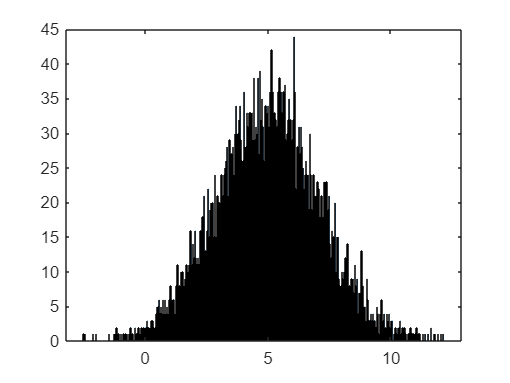

histogram(normrnd(5, 2, [1,10000]), 1000)

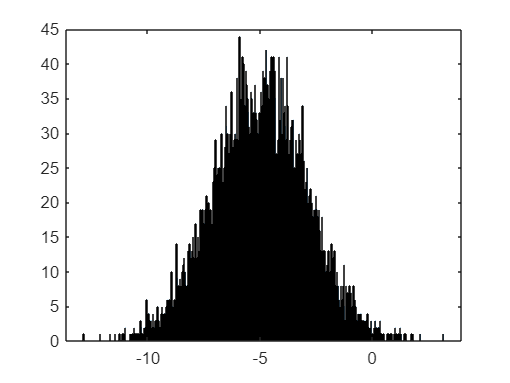

histogram(normrnd(-5, 2, [1,10000]), 1000)

**Př. 4: **Náhodná veličina A má E(X)=5 a D(X)=4, náhodná veličina B má E(X)=3 a D(X)=6, náhodná veličina C má E(X)=2 a D(X)=8. (Jsou nezávislé.) Vypočtěte střední hodnotu a rozptyl výsledné náhodné veličiny X, která je dána vzorcem X=A+B+C a Y=A+B-C**.**

E_X = 5 + 3 + 2
D_X = 4 + 6 + 8

**Př. 6.: **Náhodná veličina A má E(X)=5 a D(X)=4, náhodná veličina B má E(X)=0 a D(X)=16. Vypočtěte střední hodnotu a rozptyl výsledné náhodné veličiny X, která je dána vzorcem X=A+3*B.

E_X = 5 + 0

E_X = 5

D_X = 4 + (3^2)*16 % Tbh nevim, proč ta trojka musí být na druhou

D_X = 148

**Př. 7.:** Máte vygenerováno 1000 náhodných čísel z rovnoměrného rozdělení <0,1>. Určete pravděpodobnost, že průměr všech vygenerovaných čísel bude vyšší než 0.520.

E_X = (0 + 1) / 2 % Střední hodnota

E_X = 0.5000

D_X = (0 - 1)^2 / 12 % Rozptyl

D_X = 0.0833

n = 1000 % průměr

n = 1000


% N(E_X, D_X * 1 / n)
normcdf(1 - 0.52, E_X, sqrt(D_X * 1 / n))

ans = 0.0142

**Př. 8**: Životnost komponenty má exponenciální rozdělení se střední hodnotou 5 let. Určete pravděpodobnost, že 100 náhodně vybraných komponent bude mít v průměru životnost nižší než 4 roky.

E_X = 5 % = 1 / lambda 

E_X = 5

D_X = 5^2 % = 1 / lambda^2

D_X = 25

n = 100

n = 100


prumer = normcdf(4, E_X, sqrt(D_X / n))

prumer = 0.0228

**Př. 9.: **Zatížení letadla s 64 místy nemá překročit 6000 kg. Jaká je pravděpodobnost, že při plném obsazení bude tato hodnota překročena, má-li hmotnost cestujícího střední hodnotu 90 kg a směrodatnou odchylku 10 kg.

E_X = 90

E_X = 90

D_X = 10^2

D_X = 100

n = 64 % součet

n = 64


1 - normcdf(6000, n * E_X, sqrt(n * D_X))

ans = 0.0013

**Př. 10.:** Počet chyb na jedné straně textu má střední hodnotu 3 a rozptyl 4. Jaká je pravděpodobnost, že na 400 stranách bude méně než 1000 chyb.

E_X = 3

E_X = 3

D_X = 4

D_X = 4

n = 400

n = 400


normcdf(1000, n * E_X, sqrt(n * D_X))

ans = 2.8665e-07

**Př. 11.: **Stokrát hodíme šestistěnnou kostkou. Jaká je pravděpodobnost, že součet hodů bude mezi 320 a 380.

n = 100

n = 100

E_X = 1/6 + 2/6 + 3/6 + 4/6 + 5/6 + 1

E_X = 3.5000

D_X = (1 - 3.5)^2 / 6 + (2 - 3.5)^2 / 6 + (3 - 3.5)^2 / 6 + (4 - 3.5)^2 / 6 + (5 - 3.5)^2 / 6 + (6 - 3.5)^2 / 6

D_X = 2.9167


normcdf(380.5, n * E_X, sqrt(n * D_X)) - normcdf(319.5, n * E_X, sqrt(n * D_X))

ans = 0.9259

**Př. 12.: **600 krát hodíme kostkou. Pomocí binomického rozdělení, Poissonova rozdělení a centrální limitní věty určete, jaká je pravděpodobnost, že šestka padne 105 a vícekrát.

n = 600

n = 600

p = 1/6

p = 0.1667


1 - binocdf(104.5, n, 1/6)

ans = 0.3078

1 - poisscdf(104.5, n * 1/6)

ans = 0.3216


% Střední hodnota binomického rozdělení
E_X = n * p

E_X = 100

% Rozptyl binomického rozdělení
D_X = n * p * (1 - p)

D_X = 83.3333

prob_normal = 1 - normcdf(104.5, E_X, sqrt(D_X))

prob_normal = 0.3110

**Př. 13.:** V osudí je 16 bílých a 14 černých koulí. Jaká je pravděpodobnost, že při 150 tazích jedné koule (s vracením) vytáhneme bílou právě 77x.

a) Řešte pomocí binomického rozdělení.

b) Řešte pomocí Poissonova rozdělení.

c) Řešte pomocí centrální limitní věty.

n = 150

n = 150

p = 16/30

p = 0.5333


binopdf(77, n, p)

ans = 0.0577

poisspdf(77, n * p)

ans = 0.0429


E_X = n * p

E_X = 80

D_X = n * p * (1 - p)

D_X = 37.3333


normpdf(77, E_X, sqrt(D_X))

ans = 0.0579

**Př. 14**: Průměrný plat v České republice je 27 000 Kč se směrodatnou odchylkou 8000 Kč. Průměrné náklady na bydlení jsou 7000 Kč se směrodatnou odchylkou 2000 Kč. Vypočtěte pravděpodobnost, že člověku zůstane alespoň 25000 Kč, jestliže z platu odečteme náklady na bydlení. 

E = 27000 - 7000

E = 20000

D = 8000^2 + 2000^2

D = 68000000


1 - normcdf(25000, E, sqrt(D))

ans = 0.2721

**Př. 15**: V roce 2015 a 2016 probíhal průzkum ohledně měsíčních výdajů za pivo. Zjistěte pravděpodobnost, že v roce 2016 dávají lidé za pivo více než v roce 2015.

x2015=[587,124,651,1212,1074,523,273,800,485,961,1683,2411]

x2015 =          587         124         651        1212        1074         523         273         800         485         961        1683        2411


x2016=[121,524,2612,847,1310,1521,951,1000,521,12,190,263,321,587,953]

x2016 =          121         524        2612         847        1310        1521         951        1000         521          12         190         263         321         587         953



E = mean(x2016) - mean(x2015)

E = -116.4667

D = (var(x2015) / length(x2015)) + (var(x2016)/length(x2016))

D = 6.4232e+04


1 - normcdf(0, E, sqrt(D))

ans = 0.3229

n = 1000

n = 1000

p = 168 / 1000

p = 0.1680


pi = 0.55

pi = 0.5500

normcdf((p-pi)/sqrt(pi*(1-pi)/n), 0, 1)

ans = 1.5904e-265

n = 100;

n =    100


pi = 0.6;

pi =    0.600000000000000



p = 0.45;
1 - normcdf((p-pi)/sqrt(pi *(1-pi)/n), 0, 1)

ans =    0.998900176469444



p = 0.5;
1 - normcdf((p-pi)/sqrt(pi *(1-pi)/n), 0, 1)

ans =    0.979386583331418



p = 0.55;
1 - normcdf((p-pi)/sqrt(pi *(1-pi)/n), 0, 1)

ans =    0.846282917036302



p = 0.59;
1 - normcdf((p-pi)/sqrt(pi *(1-pi)/n), 0, 1)

ans =    0.580871756807087



p = 0.60;
1 - normcdf((p-pi)/sqrt(pi *(1-pi)/n), 0, 1)

ans =    0.500000000000000



p = 0.61;
1 - normcdf((p-pi)/sqrt(pi *(1-pi)/n), 0, 1)

ans =    0.419128243192913



p = 0.65;
1 - normcdf((p-pi)/sqrt(pi *(1-pi)/n), 0, 1)

ans =    0.153717082963697



p = 0.70;
1 - normcdf((p-pi)/sqrt(pi *(1-pi)/n), 0, 1)

ans =    0.020613416668582


n_1 = 250

n_1 =    250


n_2 = 340

n_2 =    340



pi_1 = 62/n_1

pi_1 =    0.248000000000000


pi_2 = 141/n_2

pi_2 =    0.414705882352941



E = pi_2 - pi_1

E =    0.166705882352941


D = pi_1 * (1 - pi_1) / n_1 + pi_2 * (1 - pi_2) / n_2

D =    0.001459880804396



1 - normcdf(0.1, E, sqrt(D))

ans =    0.959580968325021


chi2inv(0.05, 10)

ans =    3.940299136119060


chi2inv(0.95, 10)

ans =   18.307038053275139


1 - chi2cdf(20, 12)

ans =    0.067085962879032


**Př. 25.:** Určete pravděpodobnost, že Studentovo rozdělení s 2, 4, 10, 100 stupni volnosti nabývá P(X>1). Určete pravděpodobnost, i pro normované normální rozdělení

1 - tcdf(1, 2)

ans = 0.2113

1 - tcdf(1, 4)

ans = 0.1870

1 - tcdf(1, 10)

ans = 0.1704

1 - tcdf(1, 100)

ans = 0.1599

ans = -1.8125

ans = 1.8125

**Př. 26.: **Zjistěte 5% a 95% kvantil Studentova rozdělení s 10 stupni volnosti.

tinv(0.05, 10)
tinv(0.95, 10)

**Př. 28.: **Zjistěte 5% a 95% kvantil F rozdělení s 10 a 5 stupni volnosti. Dále určete 5% a 95% kvantil s 5 a 10 stupni volnosti. Zkuste odhadnout jaký je mezi výsledky vztah.

finv(0.05, 10, 5)

ans = 0.3007

finv(0.95, 10, 5)

ans = 4.7351

finv(0.05, 5, 10)

ans = 0.2112

finv(0.95, 5, 10)

ans = 3.3258